# MNIST - handwritten digits recognition using kNN

clear;clc

## Including useful paths

oldpath = addpath('./data', './utils');

## Data extraction

% Specifying data file names
filenameImagesTrain = 'train-images-idx3-ubyte.gz';
filenameLabelsTrain = 'train-labels-idx1-ubyte.gz';
filenameImagesTest = 't10k-images-idx3-ubyte.gz';
filenameLabelsTest = 't10k-labels-idx1-ubyte.gz';

% Loading training sets
XTrain = processImagesMNIST(filenameImagesTrain);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processLabelsMNIST(filenameLabelsTrain);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest = processImagesMNIST(filenameImagesTest);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processLabelsMNIST(filenameLabelsTest);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


## Data pre-processing

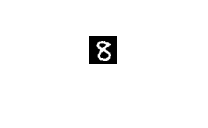

% Illustraring a sample
imshow(XTest(:,:,1,900))
set(gca,'YTick',[])
set(gca,'XTick',[])

size(XTest) % data size / structure

ans =           28          28           1       10000


% Rearranging the data, so that the data is in appropriate form for training
XTest = squeeze(reshape(XTest, [], 1, 1,size(XTest, 4)))';
XTrain = squeeze(reshape(XTrain, [], 1, 1,size(XTrain, 4)))';
YTest = YTest';
YTrain = YTrain';

## Training a k-nearest neighbor classifier

% Setting k to 10, i.e., letting the 10 nearest neighbors "to vote".
k = 10;

% Generating a kNN model
mdl_knn = fitcknn(XTrain,YTrain,'Distance','euclidean',...
    'NumNeighbors',k);

## Testing the model

YPreds = zeros(length(YTest), 1);
for i = 1:length(YTest)
    % Predicting the i-th testing sample using the kNN model
    [YPreds(i,1), scores, ~] = predict(mdl_knn, XTest(i,:));
    
    if rem(i,100) == 0 % Displaying message log, in every 100 iterations
        disp(['The ', num2str(i), '-th sample has been predicted. ' ...
            'Prediction accuracy is ' num2str( (round(sum(YPreds(1:i) == YTest(1:i), 'all')/i, 4))*100), ...
            '% to date.'])
    end
end

The 100-th sample has been predicted. Prediction accuracy is 97% to date.
The 200-th sample has been predicted. Prediction accuracy is 97.5% to date.
The 300-th sample has been predicted. Prediction accuracy is 97.67% to date.
The 400-th sample has been predicted. Prediction accuracy is 96.5% to date.
The 500-th sample has been predicted. Prediction accuracy is 95.8% to date.
The 600-th sample has been predicted. Prediction accuracy is 95.67% to date.
The 700-th sample has been predicted. Prediction accuracy is 95.43% to date.
The 800-th sample has been predicted. Prediction accuracy is 95.5% to date.
The 900-th sample has been predicted. Prediction accuracy is 95.78% to date.
The 1000-th sample has been predicted. Prediction accuracy is 95.5% to date.
The 1100-th sample has been predicted. Prediction accuracy is 95.55% to date.
The 1200-th sample has been predicted. Prediction accuracy is 95.42% to date.
The 1300-th sample has been predicted. Prediction accuracy is 95.23% to date.
The